# Analysis of parameter variation

determine the affect of altering various battery parameters 

load batteryParams.mat;
load ukfBatteryParams.mat;
global batteryParams;

## Increasing R0

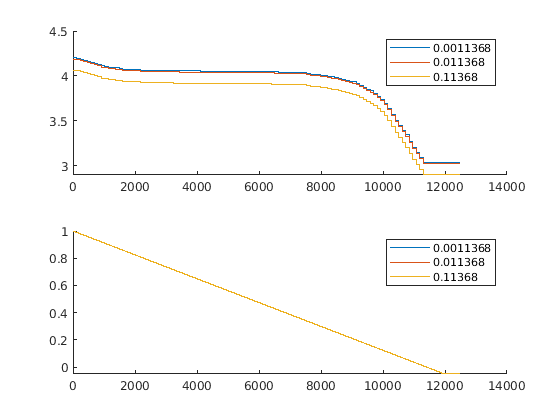

prior = batteryParams.R0;
factor = 10;
[voltages, socs, paramVals, batteryParams] = getSimResults(batteryParams, 'R0', factor);
batteryParams.R0 = prior;
save('batteryParams.mat', 'batteryParams');
f1 = plotFig(voltages, socs, paramVals, 1);

Changing R0 changes the output voltage, but the voltage curve and the SOC are unaffected. 

## Decrease Q

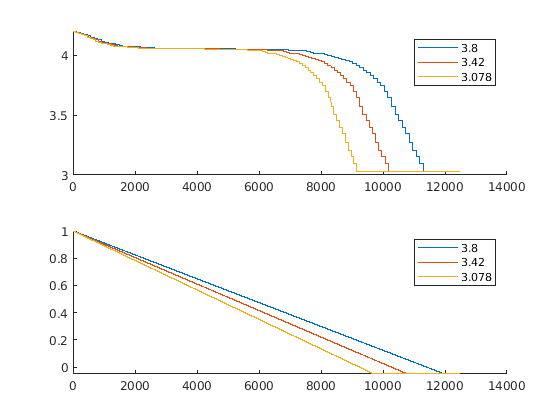

prior = batteryParams.Q;
factor = .9;
[voltages, socs, paramVals, batteryParams] = getSimResults(batteryParams, 'Q', factor);
batteryParams.Q = prior;
save('batteryParams.mat', 'batteryParams');
f2 = plotFig(voltages, socs, paramVals, 2);

Decreasing Q decreases the battery capacity and SOC slope

## Decrease coulombic efficiency by increasing batteryParams.n

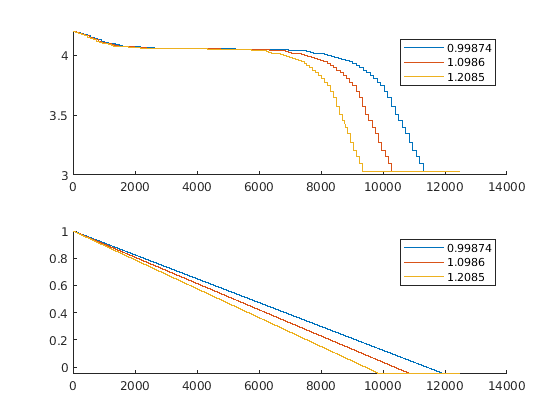

prior = batteryParams.n;
factor = 1.1;
[voltages, socs, paramVals, batteryParams] = getSimResults(batteryParams, 'n', factor);
batteryParams.n = prior;
save('batteryParams.mat', 'batteryParams');
f3 = plotFig(voltages, socs, paramVals, 3);

Altering coloumbic efficieny results in similar behavior to altering capacity

## increasing batteryParams.R ( the resistor in the R-C pair)

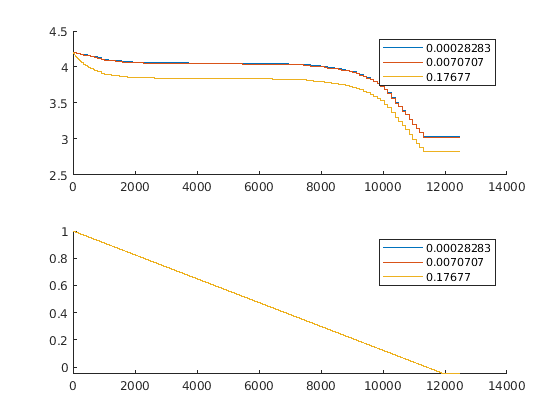

prior = batteryParams.R;
factor = 25;
[voltages, socs, paramVals, batteryParams] = getSimResults(batteryParams, 'R', factor);
batteryParams.R = prior;
save('batteryParams.mat', 'batteryParams');
f4 = plotFig(voltages, socs, paramVals, 4);

Increasing R affects the voltage curve, but not the SOC slope

## Altering batteryParams.RC (the capacitor in the R-C pair)

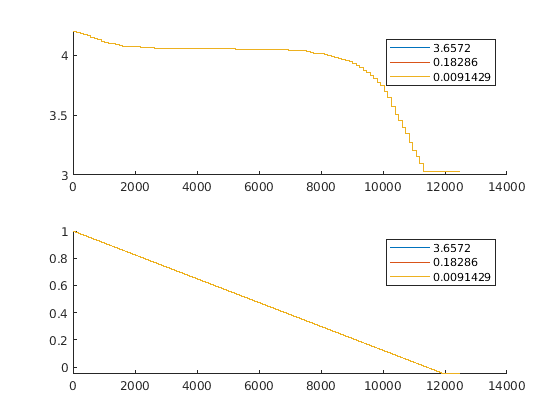

prior = batteryParams.RC;
% many, many factors were tried. from 10000 to -10000 
% nothing had an effect, I focused in the saturation range
factor = .05;
[voltages, socs, paramVals, batteryParams] = getSimResults(batteryParams, 'RC', factor);
batteryParams.RC = prior;
save('batteryParams.mat', 'batteryParams');
f5 = plotFig(voltages, socs, paramVals, 5);

Changing this parameter does not alter the SOC slope or voltage curve

## Degrade R0, R, and Q at the same time

- Similar to the path planning paper, they degraded R-0 and Q

disp(batteryParams.R);

   2.8283e-04



disp(batteryParams.R0);

    0.0011



disp(batteryParams.Q);

    3.8000



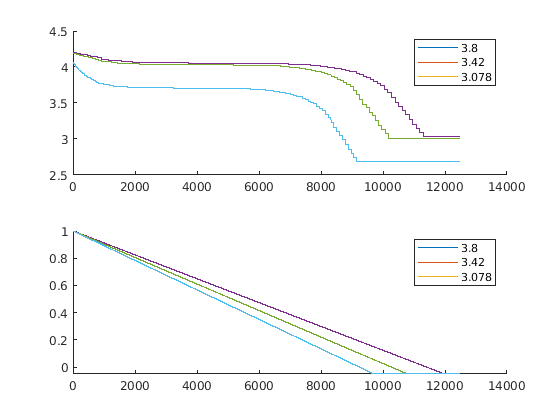

names = ['a','b','c'];
for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    rs.(names(i)) = batteryParams.R;
    r0s.(names(i)) = batteryParams.R0;
    qs.(names(i)) = batteryParams.Q;
    batteryParams.R = batteryParams.R * 25;
    batteryParams.R0 = batteryParams.R0 * 10;
    batteryParams.Q = batteryParams.Q * .9;
    save('batteryParams.mat', 'batteryParams');
end
batteryParams.R = rs.a;
batteryParams.R0 = r0s.a;
batteryParams.Q = qs.a;
save('batteryParams.mat', 'batteryParams');

f6 = plotFig(voltages, socs, qs, 6);

## Plot function

function fig = plotFig(voltages, socs, param, id)
    fig = figure(id);
    subplot(2,1,1);
    hold on;
    plot(voltages.a);
    plot(voltages.b);
    plot(voltages.c);
    hold off;
    legend(num2str(param.a), num2str(param.b), num2str(param.c));
    
    subplot(2,1,2);
    hold on;
    plot(socs.a);
    plot(socs.b);
    plot(socs.c);
    hold off;
    legend(num2str(param.a), num2str(param.b), num2str(param.c));
end



## sim the model function

- sims 3 times, degrading a parameter each iteration

function [voltages, socs, paramVals, batteryParams] = getSimResults(batteryParams, param, factor)
    % placeolder for dynamic variable creation
    names = ['a', 'b', 'c'];
    for i = 1:3
        simout = sim('batteryMine');
        voltages.(names(i)) = simout.voltage.Data;
        socs.(names(i)) = simout.soc.Data;
        paramVals.(names(i)) = batteryParams.(param);
        batteryParams.(param) = batteryParams.(param) * factor;
        save('batteryParams.mat', 'batteryParams');
    end
end





